rng('default')
rng(1234)
cd /Users/serg/github_projects/QASS_SVM/data

X = ( -3:0.01:3)';
Y = sinc(X) + 0.1.*randn(length(X), 1);

Xtrain = X(1:2:end);
Ytrain = Y(1:2:end);
Xtest = X(2:2:end);
Ytest = Y(2:2:end);

type='function estimation';
l_sig=[1, 10, 100, 1000, 10000, 100000, 1000000];
l_gam=[1, 10, 100, 1000, 10000, 100000, 1000000];

l_err=[];

i=1; 
for gam=l_gam,
    j=1;
    for sig2=l_sig,
    
    [alpha,b] = trainlssvm({Xtrain, Ytrain, type, gam, sig2, 'RBF_kernel'});
    [Yht, Zt] = simlssvm({Xtrain, Ytrain, type, gam, sig2,'RBF_kernel'}, {alpha,b}, Xtest);
    err = sum((Ytest-Yht).^2); 
    l_err(i,j)=err;
     
    fprintf('\n For RBF gamma = %d, sigma^2 = %d: mse = %d \n', gam, sig2, err) ;      
    j=j+1;
    end
    i=i+1;
end


 For RBF gamma = 1, sigma^2 = 1: mse = 1.569048e+01 

 For RBF gamma = 1, sigma^2 = 10: mse = 3.509019e+01 

 For RBF gamma = 1, sigma^2 = 100: mse = 4.204795e+01 

 For RBF gamma = 1, sigma^2 = 1000: mse = 4.234285e+01 

 For RBF gamma = 1, sigma^2 = 10000: mse = 4.234933e+01 

 For RBF gamma = 1, sigma^2 = 100000: mse = 4.234982e+01 

 For RBF gamma = 1, sigma^2 = 1000000: mse = 4.234987e+01 

 For RBF gamma = 10, sigma^2 = 1: mse = 9.911903e+00 

 For RBF gamma = 10, sigma^2 = 10: mse = 3.399892e+01 

 For RBF gamma = 10, sigma^2 = 100: mse = 4.001490e+01 

 For RBF gamma = 10, sigma^2 = 1000: mse = 4.230734e+01 

 For RBF gamma = 10, sigma^2 = 10000: mse = 4.234555e+01 

 For RBF gamma = 10, sigma^2 = 100000: mse = 4.234936e+01 

 For RBF gamma = 10, sigma^2 = 1000000: mse = 4.234982e+01 

 For RBF gamma = 100, sigma^2 = 1: mse = 4.623103e+00 

 For RBF gamma = 100, sigma^2 = 10: mse = 3.266058e+01 

 For RBF gamma = 100, sigma^2 = 100: mse = 3.537911e+01 

 For RBF gamma = 100, s

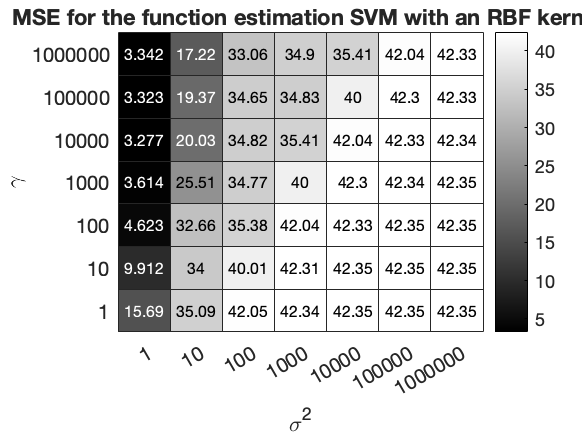

h = heatmap(l_err);
h.XDisplayLabels = string(round(l_sig));
h.YDisplayLabels = string(round(l_gam));
h.YDisplayData = flipud(h.YDisplayData);
h.NodeChildren(3).YDir='normal';  
title('MSE for the function estimation SVM with an RBF kernl');
ylabel('\gamma');
xlabel('\sigma^2');
colormap(gray);


exportgraphics(h,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_1.png','Resolution',300)

type='function estimation';
gam = 1000000;
sig2 = 1;
[alpha,b] = trainlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel'});

figure; 
plotlssvm({Xtrain,Ytrain,type,gam,sig2,'RBF_kernel','preprocess'},{alpha,b});

Start Plotting...finished


hold on
scatter(Xtest,Ytest,5,'r')
colormap(gray);
[h icons] = legend('LSSVM','Training', 'Testing')

h =   Legend (LSSVM, Training, Testing) with properties:

         String: {'LSSVM'  'Training'  'Testing'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.759821428571429 0.815476180754957 0.13125 0.0904761904761905]
          Units: 'normalized'

  Show all properties


icons =   8×1 graphics array:

  Text     (LSSVM)
  Text     (Training)
  Text     (Testing)
  Line     (LSSVM)
  Line     (LSSVM)
  Line     (Training)
  Line     (Training)
  Group    (Testing)


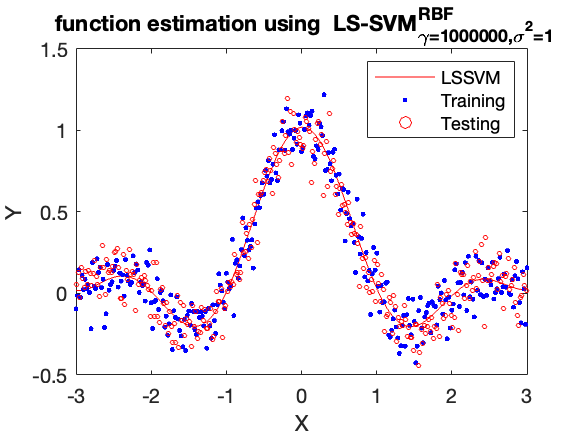


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_2.png','Resolution',300)

type='function estimation';

run=[1:100];
simplex=[];
for r=run,
    [gam , sig2, cost] = tunelssvm ({ Xtrain , Ytrain , 'function estimation', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm',{10, 'mse'});
    simplex=[simplex; gam, sig2, cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.5522
                                          [sig2]        0.23881
                                          F(X)=         0.01258
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   6.5522     0.23881

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     1.258018e-02     1.8798        -1.4321      initial 
     2           5     1.258018e-02     1.8798        -1.4321      contract outside 
     3           7     1.258018e-02     1.8798        -1.4321      contract inside 
     4          11     1.258018e-02     1.8798       

fprintf('\n RBF: median gamma = %.2f  ', median(simplex(:,1)))


 RBF: median gamma = 13.59  

fprintf('\n RBF: median sig = %.2f  ', median(simplex(:,2)))


 RBF: median sig = 0.30  

fprintf('\n RBF: median cost = %.2f  ', median(simplex(:,3)))


 RBF: median cost = 0.01  

blackColor = [0 0 0];
%Simplex
%Gamma
[f,xi] = ksdensity(log(simplex(:,1)));
fprintf('\n SIMPLEX: median gamma = %.2f  ', median(simplex(:,1)))


 SIMPLEX: median gamma = 13.59  

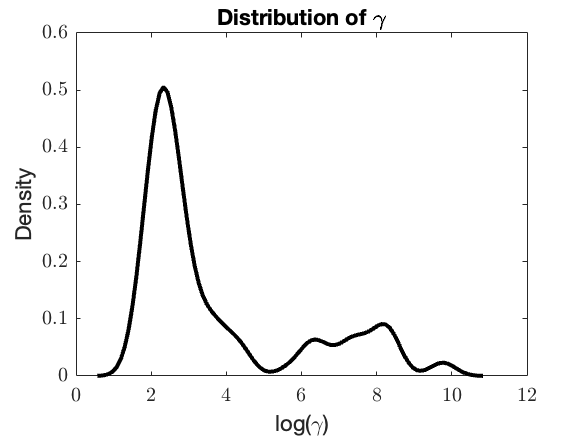


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\gamma)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_3.png','Resolution',300)



%Simplex
%Sigma
[f,xi] = ksdensity(log(simplex(:,2)));
fprintf('\n SIMPLEX: median sigma = %.2f  ', median(simplex(:,2)))


 SIMPLEX: median sigma = 0.30  

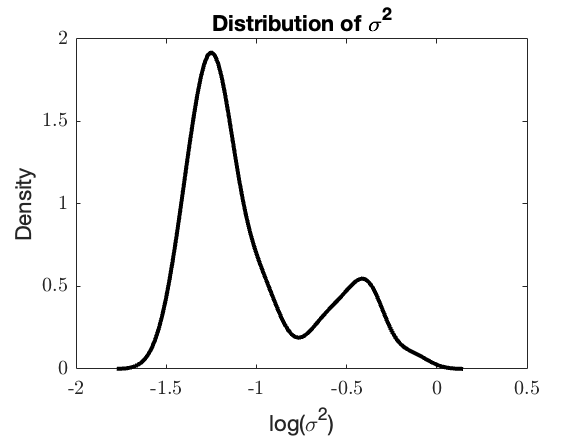



figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)

title('Distribution of \sigma^2');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\sigma^2)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_4.png','Resolution',300)



%Simplex
%Cost (error)
[f,xi] = ksdensity(log(simplex(:,3)));
fprintf('\n SIMPLEX: median cost = %.2f  ', median(simplex(:,3)))


 SIMPLEX: median cost = 0.01  

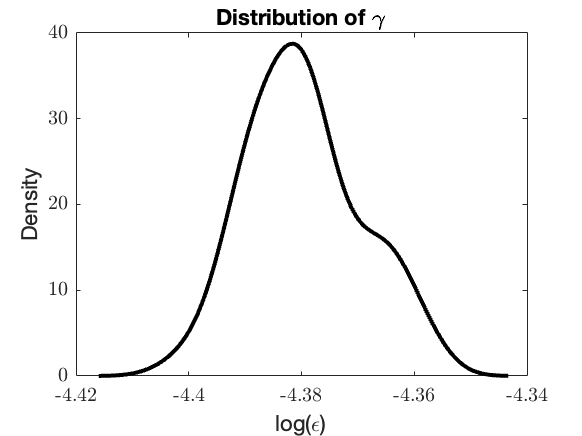


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\epsilon)');
ylabel('Density');


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_5.png','Resolution',300)

type='function estimation';

run=[1:100];
gird=[];
for r=run,
    [gam , sig2, cost] = tunelssvm ({ Xtrain , Ytrain , 'function estimation', [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm',{10, 'mse'});
    gird=[gird; gam, sig2, cost];
end


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.7628
                                          [sig2]        0.24955
                                          F(X)=         0.012551
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.3367    0.020484
    cost of starting values:           0.014289
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.33669848       1003.684
                          [sig2]        0.020484      3.0401
 
OPTIMIZATION IN LOG SCALE...


grain =      7


FIRST ITERATION:
   X=1.5781     -1.3881 ,F(X)=0.012552;
ITERATION: 2
  dF=1.409e-06, dX=0.49226, X=2.0654     -1.3183 ,F(X)=0.01255;
Obtained hyper-parameters: [gamma sig2]: 7.8884     0.26758

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.9518
                                          [sig2]        0.20541
                                          F(X)=         0.012318
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.24653    0.016861
    cost of starting values:           0.015693
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.2465349      734.9103
                     

grain =      7


FIRST ITERATION:
   X=2.5997     -1.5828 ,F(X)=0.012334;
ITERATION: 2
  dF=1.9686e-05, dX=0.46398, X=2.1414     -1.5108 ,F(X)=0.012314;
Obtained hyper-parameters: [gamma sig2]: 8.5112     0.22074

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         107.8651
                                          [sig2]        0.35644
                                          F(X)=         0.012525
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.3703    0.029258
    cost of starting values:           0.013143
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         5.37028506      16008.5941
               

grain =      7


FIRST ITERATION:
   X=3.0142     -1.0316 ,F(X)=0.012478;
ITERATION: 2
  dF=1.4985e-05, dX=1.1436, X=1.908     -1.3218 ,F(X)=0.012463;
Obtained hyper-parameters: [gamma sig2]: 6.7397     0.26667

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         9.513
                                          [sig2]        0.28033
                                          F(X)=         0.01264
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.47362    0.023011
    cost of starting values:           0.01366
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.47362435      1411.8543
                      

grain =      7


FIRST ITERATION:
   X=7.2527    -0.43847 ,F(X)=0.012648;
ITERATION: 2
  dF=8.4616e-06, dX=0.61784, X=7.8695    -0.40336 ,F(X)=0.012639;
Obtained hyper-parameters: [gamma sig2]: 2616.2492     0.66806855

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.8474
                                          [sig2]        0.26425
                                          F(X)=         0.01237
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.3907    0.021691
    cost of starting values:           0.013855
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.39070007      1164.6605
             

grain =      7


FIRST ITERATION:
   X=7.0602    -0.49754 ,F(X)=0.012371;
ITERATION: 2
  dF=0, dX=0, X=7.0602    -0.49754 ,F(X)=0.012371;
Obtained hyper-parameters: [gamma sig2]: 7.8474     0.26425

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         13.0748
                                          [sig2]        0.28871
                                          F(X)=         0.012435
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.65096    0.023699
    cost of starting values:           0.01319
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.65095651       1940.474
                          [sig2]

grain =      7


FIRST ITERATION:
   X=7.5707    -0.40901 ,F(X)=0.012433;
ITERATION: 2
  dF=0, dX=0, X=7.5707    -0.40901 ,F(X)=0.012433;
Obtained hyper-parameters: [gamma sig2]: 1940.474     0.66431087

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         8.2573
                                          [sig2]        0.23606
                                          F(X)=         0.012336
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.41111    0.019377
    cost of starting values:           0.014095
    time needed for 1 evaluation (sec):0.06
    limits of the grid:   [gam]         0.41110769      1225.4947
                          [

grain =      7


FIRST ITERATION:
   X=1.7778     -1.4437 ,F(X)=0.012335;
ITERATION: 2
  dF=6.5194e-06, dX=0.57221, X=2.3228     -1.2693 ,F(X)=0.012329;
Obtained hyper-parameters: [gamma sig2]: 10.204     0.281017

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1250.7112
                                          [sig2]        0.57519
                                          F(X)=         0.012366
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   62.2692    0.0472147
    cost of starting values:           0.013187
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         62.26924268      185621.9963
         

grain =      7


FIRST ITERATION:
   X=6.7981    -0.55305 ,F(X)=0.012357;
ITERATION: 2
  dF=6.2334e-07, dX=0.51773, X=6.2823    -0.59746 ,F(X)=0.012356;
Obtained hyper-parameters: [gamma sig2]: 535.025     0.5502062

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         130.5989
                                          [sig2]        0.48285
                                          F(X)=         0.012339
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   6.5021    0.039635
    cost of starting values:           0.012913
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         6.50213663      19382.5961
            

grain =      7


FIRST ITERATION:
   X=5.8721    -0.72804 ,F(X)=0.012306;
ITERATION: 2
  dF=6.8282e-07, dX=0.4826, X=6.3448     -0.6307 ,F(X)=0.012305;
Obtained hyper-parameters: [gamma sig2]: 569.5318     0.5322177

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.8096
                                          [sig2]        0.27117
                                          F(X)=         0.012609
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.28924    0.022259
    cost of starting values:           0.014848
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.2892433      862.2222
                

grain =      7


FIRST ITERATION:
   X=2.7595      -1.305 ,F(X)=0.012597;
ITERATION: 2
  dF=5.5298e-06, dX=0.92901, X=1.8379     -1.4216 ,F(X)=0.012591;
Obtained hyper-parameters: [gamma sig2]: 6.283     0.24132

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         413.0738
                                          [sig2]        0.4806
                                          F(X)=         0.012502
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   20.5657    0.0394497
    cost of starting values:           0.012911
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         20.5657329      61305.5858
               

grain =      7


FIRST ITERATION:
   X=5.6903    -0.73273 ,F(X)=0.0125;
ITERATION: 2
  dF=1.3971e-06, dX=1.5661, X=4.1601      -1.066 ,F(X)=0.012498;
Obtained hyper-parameters: [gamma sig2]: 64.0752     0.344366

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.612
                                          [sig2]        0.25678
                                          F(X)=         0.012559
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.37898    0.021078
    cost of starting values:           0.014204
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.37898083      1129.7259
                   

grain =      7


FIRST ITERATION:
   X=7.0297     -0.5262 ,F(X)=0.012564;
ITERATION: 2
  dF=0, dX=0, X=7.0297     -0.5262 ,F(X)=0.012564;
Obtained hyper-parameters: [gamma sig2]: 7.612     0.25678

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         22.7397
                                          [sig2]        0.29763
                                          F(X)=         0.012417
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.1321    0.024431
    cost of starting values:           0.013009
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.1321439      3374.8733
                          [sig2]  

grain =      7


FIRST ITERATION:
   X=8.1241    -0.37856 ,F(X)=0.012399;
ITERATION: 2
  dF=0, dX=0, X=8.1241    -0.37856 ,F(X)=0.012399;
Obtained hyper-parameters: [gamma sig2]: 3374.8733     0.68484679

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.182
                                          [sig2]        0.18986
                                          F(X)=         0.012499
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.10863    0.015585
    cost of starting values:           0.024671
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.1086332      323.8309
                          [si

grain =      7


FIRST ITERATION:
   X=1.7802     -1.6614 ,F(X)=0.012492;
ITERATION: 2
  dF=2.671e-05, dX=0.20496, X=1.8111     -1.4588 ,F(X)=0.012465;
Obtained hyper-parameters: [gamma sig2]: 6.1171     0.23251

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         32.0265
                                          [sig2]        0.33207
                                          F(X)=         0.012432
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.5945    0.027258
    cost of starting values:           0.012988
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.5945036      4753.1482
                   

grain =      7


FIRST ITERATION:
   X=3.1332     -1.1024 ,F(X)=0.012431;
ITERATION: 2
  dF=3.4971e-07, dX=1.0548, X=2.1188     -1.3913 ,F(X)=0.01243;
Obtained hyper-parameters: [gamma sig2]: 8.3213     0.24875

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         54.0427
                                          [sig2]        0.39916
                                          F(X)=         0.012483
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.6906    0.032765
    cost of starting values:           0.013046
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         2.6906292      8020.6525
                    

grain =      7


FIRST ITERATION:
   X=3.6564    -0.91839 ,F(X)=0.01248;
ITERATION: 2
  dF=1.2356e-05, dX=0.97539, X=2.6965     -1.0915 ,F(X)=0.012467;
Obtained hyper-parameters: [gamma sig2]: 14.8284     0.335703

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         8.1898
                                          [sig2]        0.28503
                                          F(X)=         0.012364
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.40774    0.023397
    cost of starting values:           0.013623
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.40774387      1215.4674
                

grain =      7


FIRST ITERATION:
   X=3.1029     -1.2552 ,F(X)=0.012359;
ITERATION: 2
  dF=5.1359e-06, dX=1.0343, X=4.1044    -0.99716 ,F(X)=0.012354;
Obtained hyper-parameters: [gamma sig2]: 60.6086     0.368927

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         18.2534
                                          [sig2]        0.28967
                                          F(X)=         0.012487
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.90878    0.023778
    cost of starting values:           0.012996
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.908781       2709.038
                 

grain =      7


FIRST ITERATION:
   X=7.9043    -0.40567 ,F(X)=0.012462;
ITERATION: 2
  dF=0, dX=0, X=7.9043    -0.40567 ,F(X)=0.012462;
Obtained hyper-parameters: [gamma sig2]: 2709.038     0.66652828

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         110.6971
                                          [sig2]        0.36035
                                          F(X)=         0.012492
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   5.5113    0.029579
    cost of starting values:           0.012854
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         5.51128209      16428.9004
                         

grain =      7


FIRST ITERATION:
   X=9.7068    -0.18735 ,F(X)=0.012474;
ITERATION: 2
  dF=9.2089e-06, dX=1.5054, X=8.2164    -0.39996 ,F(X)=0.012464;
Obtained hyper-parameters: [gamma sig2]: 3701.3287     0.67034623

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         12.1129
                                          [sig2]        0.31929
                                          F(X)=         0.01236
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.60307    0.026209
    cost of starting values:           0.013044
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.6030662       1797.715
             

grain =      7


FIRST ITERATION:
   X=0.82761      -1.975 ,F(X)=0.012366;
ITERATION: 2
  dF=2.4754e-05, dX=0.82496, X=1.5125     -1.5152 ,F(X)=0.012341;
Obtained hyper-parameters: [gamma sig2]: 4.5382     0.21977

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         9.8789
                                          [sig2]        0.27984
                                          F(X)=         0.012364
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.49184    0.022971
    cost of starting values:           0.01333
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.49184243      1466.1616
                 

grain =      7


FIRST ITERATION:
   X=1.9571     -1.2735 ,F(X)=0.012376;
ITERATION: 2
  dF=1.3408e-05, dX=0.52959, X=2.485     -1.2318 ,F(X)=0.012363;
Obtained hyper-parameters: [gamma sig2]: 12.0014     0.291761

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         8.9957
                                          [sig2]        0.22437
                                          F(X)=         0.012455
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.44787    0.018418
    cost of starting values:           0.013624
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.44787039      1335.0828
                

grain =      7


FIRST ITERATION:
   X=1.8634     -1.4945 ,F(X)=0.012448;
ITERATION: 2
  dF=7.9457e-06, dX=1.0909, X=2.9118     -1.1929 ,F(X)=0.01244;
Obtained hyper-parameters: [gamma sig2]: 18.39     0.303346

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.9455
                                          [sig2]        0.21718
                                          F(X)=         0.01248
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.3458    0.017827
    cost of starting values:           0.014582
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.34579694      1030.8061
                     

grain =      7


FIRST ITERATION:
   X=5.6048    -0.69368 ,F(X)=0.01246;
ITERATION: 2
  dF=2.0792e-07, dX=0.5445, X=6.1452     -0.6273 ,F(X)=0.01246;
Obtained hyper-parameters: [gamma sig2]: 466.4739     0.5340334

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         952.9188
                                          [sig2]        0.59285
                                          F(X)=         0.012418
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   47.443    0.0486645
    cost of starting values:           0.013065
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         47.44303472      141425.6933
           

grain =      7


FIRST ITERATION:
   X=3.8595     -1.3561 ,F(X)=0.012421;
ITERATION: 2
  dF=3.1386e-05, dX=1.2493, X=2.6104     -1.3759 ,F(X)=0.01239;
Obtained hyper-parameters: [gamma sig2]: 13.6042     0.252616

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2825.706
                                          [sig2]        0.71407
                                          F(X)=         0.012499
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   140.6836    0.05861473
    cost of starting values:           0.013202
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         140.6836172      419371.9524
         

grain =      7


FIRST ITERATION:
   X=8.9465    -0.33677 ,F(X)=0.012509;
ITERATION: 2
  dF=1.6664e-05, dX=1.5108, X=7.4414    -0.46744 ,F(X)=0.012492;
Obtained hyper-parameters: [gamma sig2]: 1705.1616     0.62660409

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.9236
                                          [sig2]        0.085757
                                          F(X)=         0.012759
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.09577   0.0070393
    cost of starting values:           0.036738
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.09576955       285.485
            

grain =      7


FIRST ITERATION:
   X=1.6542     -1.6229 ,F(X)=0.012603;
ITERATION: 2
  dF=2.9073e-05, dX=0.61085, X=2.1636     -1.2859 ,F(X)=0.012574;
Obtained hyper-parameters: [gamma sig2]: 8.7028     0.27641

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.2942
                                          [sig2]        0.23286
                                          F(X)=         0.012552
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.21379    0.019114
    cost of starting values:           0.016487
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2137933       637.309
                   

grain =      7


FIRST ITERATION:
   X=2.4573     -1.4573 ,F(X)=0.012564;
ITERATION: 2
  dF=2.006e-05, dX=0.46398, X=1.9989     -1.3853 ,F(X)=0.012544;
Obtained hyper-parameters: [gamma sig2]: 7.3809     0.25024

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.6431
                                          [sig2]        0.2041
                                          F(X)=         0.012479
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.18138    0.016753
    cost of starting values:           0.018101
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.1813808      540.6886
                     

grain =      7


FIRST ITERATION:
   X=4.9595    -0.75583 ,F(X)=0.0125;
ITERATION: 2
  dF=2.057e-05, dX=1.4037, X=3.5737    -0.97928 ,F(X)=0.012479;
Obtained hyper-parameters: [gamma sig2]: 3.6431      0.2041

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.1742
                                          [sig2]        0.17673
                                          F(X)=         0.012677
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.15804    0.014507
    cost of starting values:           0.020369
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.1580351      471.0959
                       

grain =      7


FIRST ITERATION:
   X=0.82173     -1.7331 ,F(X)=0.012685;
ITERATION: 2
  dF=2.3605e-05, dX=1.0242, X=1.7864     -1.3893 ,F(X)=0.012662;
Obtained hyper-parameters: [gamma sig2]: 5.9682     0.24925

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         17.5632
                                          [sig2]        0.32403
                                          F(X)=         0.012322
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.87442    0.026598
    cost of starting values:           0.012931
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.87442247      2606.6166
                

grain =      7


FIRST ITERATION:
   X=2.5325     -1.1269 ,F(X)=0.01233;
ITERATION: 2
  dF=8.5137e-06, dX=0.56188, X=2.0327     -1.3837 ,F(X)=0.012321;
Obtained hyper-parameters: [gamma sig2]: 7.6345     0.25066

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         19.4246
                                          [sig2]        0.29832
                                          F(X)=         0.012498
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.96709    0.024487
    cost of starting values:           0.013029
    time needed for 1 evaluation (sec):0.05
    limits of the grid:   [gam]         0.9670929      2882.8633
                  

grain =      7


FIRST ITERATION:
   X=2.6332     -1.2096 ,F(X)=0.012482;
ITERATION: 2
  dF=4.842e-06, dX=0.97979, X=1.6778     -1.4269 ,F(X)=0.012477;
Obtained hyper-parameters: [gamma sig2]: 5.3538     0.24006

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         212.2079
                                          [sig2]        0.48284
                                          F(X)=         0.012509
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   10.5652     0.039634
    cost of starting values:           0.01301
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         10.5652076        31494.44
               

grain =      7


FIRST ITERATION:
   X=5.0242    -0.72807 ,F(X)=0.012518;
ITERATION: 2
  dF=1.8532e-05, dX=1.5661, X=3.494     -1.0614 ,F(X)=0.012499;
Obtained hyper-parameters: [gamma sig2]: 32.9173     0.345975

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         22.2459
                                          [sig2]        0.2076
                                          F(X)=         0.012587
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.1076    0.017041
    cost of starting values:           0.013267
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1.1075586      3301.5857
                   

grain =      7


FIRST ITERATION:
   X=1.4355     -1.5721 ,F(X)=0.012529;
ITERATION: 2
  dF=1.3232e-05, dX=1.1608, X=2.5667     -1.3115 ,F(X)=0.012516;
Obtained hyper-parameters: [gamma sig2]: 13.0226     0.269407

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         42.3885
                                          [sig2]        0.31135
                                          F(X)=         0.01246
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.1104    0.025558
    cost of starting values:           0.012868
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         2.1103984       6291.009
                  

grain =      7


FIRST ITERATION:
   X=3.4135     -1.1668 ,F(X)=0.012456;
ITERATION: 2
  dF=5.7539e-08, dX=0.53768, X=2.8901     -1.2898 ,F(X)=0.012456;
Obtained hyper-parameters: [gamma sig2]: 17.9954     0.275328

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         236.4072
                                          [sig2]        0.48924
                                          F(X)=         0.012565
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   11.77    0.0401595
    cost of starting values:           0.013027
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         11.7700199      35085.9348
             

grain =      7


FIRST ITERATION:
   X=6.4656     -0.7149 ,F(X)=0.012572;
ITERATION: 2
  dF=2.17e-05, dX=1.5269, X=7.9614    -0.40866 ,F(X)=0.01255;
Obtained hyper-parameters: [gamma sig2]: 2868.1619     0.66453938

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.3348
                                          [sig2]        0.1408
                                          F(X)=         0.012535
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.16603    0.011558
    cost of starting values:           0.020815
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.1660317      494.9336
                  

grain =      7


FIRST ITERATION:
   X=3.5378     -1.1271 ,F(X)=0.01246;
ITERATION: 2
  dF=3.0069e-06, dX=0.99856, X=2.5539     -1.2977 ,F(X)=0.012457;
Obtained hyper-parameters: [gamma sig2]: 12.857     0.273162

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         813.0589
                                          [sig2]        0.5546
                                          F(X)=         0.012438
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   40.4798    0.0455242
    cost of starting values:           0.013021
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         40.47982093      120668.6455
            

grain =      7


FIRST ITERATION:
   X=6.3675    -0.58951 ,F(X)=0.01244;
ITERATION: 2
  dF=3.6085e-06, dX=1.4631, X=4.9276    -0.84922 ,F(X)=0.012437;
Obtained hyper-parameters: [gamma sig2]: 138.0508     0.4277467

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         10.5541
                                          [sig2]        0.27273
                                          F(X)=         0.012608
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.52546    0.022387
    cost of starting values:           0.013635
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.5254555      1566.3608
               

grain =      7


FIRST ITERATION:
   X=2.0232     -1.2993 ,F(X)=0.012614;
ITERATION: 2
  dF=2.3914e-06, dX=1.0811, X=3.0961     -1.1667 ,F(X)=0.012611;
Obtained hyper-parameters: [gamma sig2]: 10.5541     0.272726

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         82.057
                                          [sig2]        0.43518
                                          F(X)=         0.012494
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   4.0854    0.035722
    cost of starting values:           0.012915
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         4.08537876      12178.3424
                

grain =      7


FIRST ITERATION:
   X=4.0741      -0.832 ,F(X)=0.012505;
ITERATION: 2
  dF=2.5115e-05, dX=1.4763, X=2.6508     -1.2243 ,F(X)=0.01248;
Obtained hyper-parameters: [gamma sig2]: 14.166     0.293966

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.2358
                                          [sig2]        0.22014
                                          F(X)=         0.012415
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.31046     0.01807
    cost of starting values:           0.014696
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.3104605      925.4696
                    

grain =      7


FIRST ITERATION:
   X=1.497     -1.5135 ,F(X)=0.012414;
ITERATION: 2
  dF=1.5147e-05, dX=1.1498, X=2.6085     -1.2195 ,F(X)=0.012399;
Obtained hyper-parameters: [gamma sig2]: 13.5791     0.295381

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.772
                                          [sig2]        0.15262
                                          F(X)=         0.012538
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.088222    0.012527
    cost of starting values:           0.030975
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.08822168      262.9851
                  

grain =      7


FIRST ITERATION:
   X=2.9054     -1.0465 ,F(X)=0.012429;
ITERATION: 2
  dF=1.3131e-05, dX=0.83972, X=3.7446     -1.0154 ,F(X)=0.012416;
Obtained hyper-parameters: [gamma sig2]: 42.2912     0.362241

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         624.0567
                                          [sig2]        0.47976
                                          F(X)=         0.012568
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   31.07    0.0393814
    cost of starting values:           0.013528
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         31.0699554      92618.2318
             

grain =      7


FIRST ITERATION:
   X=6.1029    -0.73446 ,F(X)=0.012559;
ITERATION: 2
  dF=1.2068e-05, dX=1.0836, X=7.163    -0.51026 ,F(X)=0.012547;
Obtained hyper-parameters: [gamma sig2]: 1290.8106     0.60033757

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         13.5405
                                          [sig2]        0.14454
                                          F(X)=         0.012504
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.67414    0.011864
    cost of starting values:           0.013876
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.67413956      2009.5817
            

grain =      7


FIRST ITERATION:
   X=3.6057     -1.1009 ,F(X)=0.012428;
ITERATION: 2
  dF=1.2331e-05, dX=1.3968, X=2.2363     -1.3758 ,F(X)=0.012415;
Obtained hyper-parameters: [gamma sig2]: 9.3582     0.25263

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.7898
                                          [sig2]        0.27007
                                          F(X)=         0.012299
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.23847    0.022168
    cost of starting values:           0.01542
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.2384684      710.8644
                     

grain =      7


FIRST ITERATION:
   X=2.5665     -1.3091 ,F(X)=0.012252;
ITERATION: 2
  dF=8.9181e-07, dX=0.45169, X=2.1175     -1.3585 ,F(X)=0.012251;
Obtained hyper-parameters: [gamma sig2]: 8.3104     0.25704

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         15.8596
                                          [sig2]        0.26615
                                          F(X)=         0.01244
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.7896    0.021847
    cost of starting values:           0.012977
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.78960058      2353.7662
                  

grain =      7


FIRST ITERATION:
   X=2.4304     -1.3237 ,F(X)=0.012432;
ITERATION: 2
  dF=5.1928e-08, dX=0.46811, X=1.9696      -1.406 ,F(X)=0.012432;
Obtained hyper-parameters: [gamma sig2]: 7.168     0.24512

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.6974
                                          [sig2]        0.20743
                                          F(X)=         0.012486
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.1343    0.017027
    cost of starting values:           0.021304
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.1342953      400.3287
                     

grain =      7


FIRST ITERATION:
   X=5.9923    -0.73961 ,F(X)=0.012453;
ITERATION: 2
  dF=1.4238e-05, dX=1.7423, X=4.2601    -0.92723 ,F(X)=0.012439;
Obtained hyper-parameters: [gamma sig2]: 70.8193      0.39565

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.5439
                                          [sig2]        0.2047
                                          F(X)=         0.012777
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.27601    0.016803
    cost of starting values:           0.016006
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2760141      822.7864
                   

grain =      7


FIRST ITERATION:
   X=1.3794     -1.5862 ,F(X)=0.012771;
ITERATION: 2
  dF=1.6033e-06, dX=0.53768, X=1.9028     -1.4632 ,F(X)=0.012769;
Obtained hyper-parameters: [gamma sig2]: 6.7046     0.23148

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         30.9256
                                          [sig2]        0.38378
                                          F(X)=         0.012411
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.5397    0.031503
    cost of starting values:           0.012721
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1.5396971      4589.7723
                  

grain =      7


FIRST ITERATION:
   X=4.4316    -0.95769 ,F(X)=0.0124;
ITERATION: 2
  dF=4.0188e-06, dX=1.4478, X=3.0135     -1.2497 ,F(X)=0.012396;
Obtained hyper-parameters: [gamma sig2]: 20.3592     0.286588

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         66.3636
                                          [sig2]        0.36922
                                          F(X)=         0.012586
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   3.304    0.030308
    cost of starting values:           0.013158
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         3.3040487      9849.2303
                    

grain =      7


FIRST ITERATION:
   X=3.8618    -0.99635 ,F(X)=0.012573;
ITERATION: 2
  dF=1.6585e-05, dX=1.4631, X=2.422     -1.2561 ,F(X)=0.012556;
Obtained hyper-parameters: [gamma sig2]: 11.268     0.284773

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1078.5526
                                          [sig2]        0.60136
                                          F(X)=         0.012454
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   53.698    0.0493627
    cost of starting values:           0.013042
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         53.69796957      160071.3913
            

grain =      7


FIRST ITERATION:
   X=6.65    -0.50856 ,F(X)=0.012465;
ITERATION: 2
  dF=1.849e-05, dX=1.5525, X=8.1982     -0.3932 ,F(X)=0.012447;
Obtained hyper-parameters: [gamma sig2]: 3634.4598     0.67489354

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1.9401
                                          [sig2]        0.1186
                                          F(X)=         0.012615
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.096593   0.0097355
    cost of starting values:           0.032081
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.09659314      287.9401
                

grain =      7


FIRST ITERATION:
   X=2.9961     -1.2986 ,F(X)=0.012544;
ITERATION: 2
  dF=1.7429e-05, dX=0.41392, X=2.5975     -1.1872 ,F(X)=0.012527;
Obtained hyper-parameters: [gamma sig2]: 13.4296      0.30508

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6380.5052
                                          [sig2]        0.77799
                                          F(X)=         0.012474
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   317.6667    0.06386131
    cost of starting values:           0.013085
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         317.666651      946950.9405
       

grain =      7


FIRST ITERATION:
   X=8.4277    -0.25104 ,F(X)=0.012481;
ITERATION: 2
  dF=0, dX=0, X=8.4277    -0.25104 ,F(X)=0.012481;
Obtained hyper-parameters: [gamma sig2]: 6380.5052     0.77798997

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         18.7734
                                          [sig2]        0.31267
                                          F(X)=         0.012513
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.93467    0.025666
    cost of starting values:           0.01311
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.93467145      2786.2163
                          

grain =      7


FIRST ITERATION:
   X=2.5991     -1.1626 ,F(X)=0.012499;
ITERATION: 2
  dF=4.9459e-06, dX=0.48769, X=2.1192     -1.2492 ,F(X)=0.012494;
Obtained hyper-parameters: [gamma sig2]: 8.3241     0.28674

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.4057
                                          [sig2]        0.23167
                                          F(X)=         0.012494
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.26913    0.019017
    cost of starting values:           0.015184
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2691321      802.2715
                   

grain =      7


FIRST ITERATION:
   X=1.3541     -1.4624 ,F(X)=0.012509;
ITERATION: 2
  dF=1.7021e-05, dX=0.52959, X=1.8821     -1.4207 ,F(X)=0.012492;
Obtained hyper-parameters: [gamma sig2]: 6.567     0.24154

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.3349
                                          [sig2]        0.26551
                                          F(X)=         0.012788
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.26561    0.021794
    cost of starting values:           0.015325
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2656072      791.7639
                    

grain =      7


FIRST ITERATION:
   X=2.6743     -1.3261 ,F(X)=0.012818;
ITERATION: 2
  dF=3.4722e-05, dX=0.45083, X=2.2404     -1.2038 ,F(X)=0.012784;
Obtained hyper-parameters: [gamma sig2]: 9.3966     0.30006

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         25.6792
                                          [sig2]        0.37689
                                          F(X)=         0.012461
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.2785    0.030937
    cost of starting values:           0.012822
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.2784911      3811.1282
                  

grain =      7


FIRST ITERATION:
   X=4.2457    -0.97581 ,F(X)=0.012461;
ITERATION: 2
  dF=1.9931e-05, dX=1.4319, X=2.8316      -1.201 ,F(X)=0.012441;
Obtained hyper-parameters: [gamma sig2]: 16.9721     0.300893

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         20.7024
                                          [sig2]        0.30986
                                          F(X)=         0.012497
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.0307    0.025435
    cost of starting values:           0.013074
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         1.0307112      3072.5067
                 

grain =      7


FIRST ITERATION:
   X=2.6969     -1.1716 ,F(X)=0.012491;
ITERATION: 2
  dF=0, dX=0, X=2.6969     -1.1716 ,F(X)=0.012491;
Obtained hyper-parameters: [gamma sig2]: 14.8339     0.309856

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.4513
                                          [sig2]        0.23005
                                          F(X)=         0.012626
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.17183    0.018884
    cost of starting values:           0.018406
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.1718289      512.2147
                          [sig2]

grain =      7


FIRST ITERATION:
   X=6.2387    -0.63612 ,F(X)=0.012607;
ITERATION: 2
  dF=0, dX=0, X=6.2387    -0.63612 ,F(X)=0.012607;
Obtained hyper-parameters: [gamma sig2]: 512.2147     0.5293447

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         9.4349
                                          [sig2]        0.26624
                                          F(X)=         0.012482
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.46973    0.021854
    cost of starting values:           0.013599
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         0.46973353      1400.2559
                          [s

grain =      7


FIRST ITERATION:
   X=1.9111     -1.3234 ,F(X)=0.012482;
ITERATION: 2
  dF=4.2075e-06, dX=0.57221, X=2.4561      -1.149 ,F(X)=0.012477;
Obtained hyper-parameters: [gamma sig2]: 11.6591     0.316945

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1675.6503
                                          [sig2]        0.66341
                                          F(X)=         0.01249
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   83.4257    0.0544559
    cost of starting values:           0.012891
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         83.42571478      248688.5508
         

grain =      7


FIRST ITERATION:
   X=8.424    -0.41036 ,F(X)=0.012494;
ITERATION: 2
  dF=4.7532e-06, dX=1.0897, X=9.4964    -0.21721 ,F(X)=0.012489;
Obtained hyper-parameters: [gamma sig2]: 13311.3642     0.804757445

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.2349
                                          [sig2]        0.25332
                                          F(X)=         0.012557
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.36021    0.020794
    cost of starting values:           0.014208
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.36020684      1073.7615
           

grain =      7


FIRST ITERATION:
   X=1.6456     -1.3731 ,F(X)=0.012563;
ITERATION: 2
  dF=4.1147e-06, dX=0.52959, X=2.1735     -1.3314 ,F(X)=0.012559;
Obtained hyper-parameters: [gamma sig2]: 7.2349     0.25332

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.4147
                                          [sig2]        0.28688
                                          F(X)=         0.01258
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.31937    0.023548
    cost of starting values:           0.014371
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.3193715      952.0331
                    

grain =      7


FIRST ITERATION:
   X=2.8586     -1.2487 ,F(X)=0.012601;
ITERATION: 2
  dF=3.2752e-05, dX=0.46558, X=2.4021     -1.1571 ,F(X)=0.012569;
Obtained hyper-parameters: [gamma sig2]: 11.0466      0.31441

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         40.5898
                                          [sig2]        0.36574
                                          F(X)=         0.012414
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.0208    0.030022
    cost of starting values:           0.012897
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         2.0208486      6024.0648
                

grain =      7


FIRST ITERATION:
   X=3.3702     -1.0058 ,F(X)=0.012421;
ITERATION: 2
  dF=1.095e-05, dX=1.4804, X=1.9704     -1.4874 ,F(X)=0.01241;
Obtained hyper-parameters: [gamma sig2]: 7.1733     0.22595

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         29.17
                                          [sig2]        0.34592
                                          F(X)=         0.012513
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.4523    0.028395
    cost of starting values:           0.012975
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.4522867      4329.2056
                       

grain =      7


FIRST ITERATION:
   X=3.0398     -1.0615 ,F(X)=0.012514;
ITERATION: 2
  dF=0, dX=0, X=3.0398     -1.0615 ,F(X)=0.012514;
Obtained hyper-parameters: [gamma sig2]: 29.17     0.345923

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.3666
                                          [sig2]        0.15899
                                          F(X)=         0.012356
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.16761    0.013051
    cost of starting values:           0.019784
    time needed for 1 evaluation (sec):0.01
    limits of the grid:   [gam]         0.1676149       499.653
                          [sig2]  

grain =      7


FIRST ITERATION:
   X=3.5472     -1.0056 ,F(X)=0.012283;
ITERATION: 2
  dF=0, dX=0, X=3.5472     -1.0056 ,F(X)=0.012283;
Obtained hyper-parameters: [gamma sig2]: 34.7176     0.365836

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         25.4688
                                          [sig2]        0.34521
                                          F(X)=         0.012556
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.268    0.028336
    cost of starting values:           0.012946
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.2680191      3779.9116
                          [sig2]

grain =      7


FIRST ITERATION:
   X=2.9041     -1.0636 ,F(X)=0.012553;
ITERATION: 2
  dF=0, dX=0, X=2.9041     -1.0636 ,F(X)=0.012553;
Obtained hyper-parameters: [gamma sig2]: 18.2492     0.345207

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.0717
                                          [sig2]        0.20359
                                          F(X)=         0.012521
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.30229    0.016712
    cost of starting values:           0.014975
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.3022942      901.1262
                          [sig2]

grain =      7


FIRST ITERATION:
   X=1.4703     -1.5917 ,F(X)=0.01251;
ITERATION: 2
  dF=1.8036e-06, dX=0.55408, X=2.0053     -1.4474 ,F(X)=0.012508;
Obtained hyper-parameters: [gamma sig2]: 7.4282     0.23518

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         262.9348
                                          [sig2]        0.4625
                                          F(X)=         0.012682
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   13.0908    0.0379645
    cost of starting values:           0.013293
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         13.0907533      39022.9856
               

grain =      7


FIRST ITERATION:
   X=5.2386     -0.7711 ,F(X)=0.012676;
ITERATION: 2
  dF=0, dX=0, X=5.2386     -0.7711 ,F(X)=0.012676;
Obtained hyper-parameters: [gamma sig2]: 188.401     0.4625027

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.3212
                                          [sig2]        0.21564
                                          F(X)=         0.0126
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.26493    0.017701
    cost of starting values:           0.01558
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2649267      789.7354
                          [sig2]  

grain =      7


FIRST ITERATION:
   X=1.3384     -1.5341 ,F(X)=0.012604;
ITERATION: 2
  dF=3.4783e-06, dX=0.52959, X=1.8663     -1.4924 ,F(X)=0.012601;
Obtained hyper-parameters: [gamma sig2]: 5.3212     0.21564

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         32.7766
                                          [sig2]        0.23386
                                          F(X)=         0.012693
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.6318    0.019196
    cost of starting values:           0.013472
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         1.6318497      4864.4755
                  

grain =      7


FIRST ITERATION:
   X=1.823      -1.453 ,F(X)=0.012628;
ITERATION: 2
  dF=2.8894e-06, dX=0.59032, X=2.4017     -1.3362 ,F(X)=0.012625;
Obtained hyper-parameters: [gamma sig2]: 11.0418     0.262843

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         39.8516
                                          [sig2]        0.38556
                                          F(X)=         0.01253
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.9841    0.031649
    cost of starting values:           0.012992
    time needed for 1 evaluation (sec):0.05
    limits of the grid:   [gam]         1.9840945      5914.5022
                  

grain =      7


FIRST ITERATION:
   X=3.3518    -0.95306 ,F(X)=0.012537;
ITERATION: 2
  dF=5.5594e-07, dX=1.0784, X=2.3386     -1.3222 ,F(X)=0.012536;
Obtained hyper-parameters: [gamma sig2]: 39.8516     0.385561

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.301
                                          [sig2]        0.28352
                                          F(X)=         0.012666
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.31371    0.023272
    cost of starting values:           0.014633
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.3137085      935.1518
                   

grain =      7


FIRST ITERATION:
   X=2.8407     -1.2605 ,F(X)=0.012673;
ITERATION: 2
  dF=1.561e-05, dX=0.95798, X=1.8835     -1.2978 ,F(X)=0.012658;
Obtained hyper-parameters: [gamma sig2]: 6.5762     0.27312

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         492.3996
                                          [sig2]        0.52354
                                          F(X)=         0.012449
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   24.5151    0.0429747
    cost of starting values:           0.013225
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         24.5151345       73078.586
              

grain =      7


FIRST ITERATION:
   X=5.866    -0.64714 ,F(X)=0.012446;
ITERATION: 2
  dF=0, dX=0, X=5.866    -0.64714 ,F(X)=0.012446;
Obtained hyper-parameters: [gamma sig2]: 352.8198     0.5235394

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         20.566
                                          [sig2]        0.30525
                                          F(X)=         0.012574
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.0239    0.025056
    cost of starting values:           0.013049
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         1.023922      3052.2686
                          [sig2] 

grain =      7


FIRST ITERATION:
   X=2.6903     -1.1866 ,F(X)=0.012561;
ITERATION: 2
  dF=0, dX=0, X=2.6903     -1.1866 ,F(X)=0.012561;
Obtained hyper-parameters: [gamma sig2]: 14.7362     0.305245

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         10.1707
                                          [sig2]        0.28983
                                          F(X)=         0.012357
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.50637    0.023791
    cost of starting values:           0.013209
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.50636851      1509.4633
                          [si

grain =      7


FIRST ITERATION:
   X=1.9862     -1.2385 ,F(X)=0.012358;
ITERATION: 2
  dF=0, dX=0, X=1.9862     -1.2385 ,F(X)=0.012358;
Obtained hyper-parameters: [gamma sig2]: 10.1707     0.289831

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         5.3638
                                          [sig2]        0.20106
                                          F(X)=         0.012382
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.26705    0.016504
    cost of starting values:           0.015445
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.2670458      796.0523
                          [sig2]

grain =      7


FIRST ITERATION:
   X=5.3463     -0.7708 ,F(X)=0.012368;
ITERATION: 2
  dF=1.2981e-06, dX=1.549, X=3.8286     -1.0803 ,F(X)=0.012367;
Obtained hyper-parameters: [gamma sig2]: 45.9987     0.339489

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         85.7445
                                          [sig2]        0.45277
                                          F(X)=         0.012841
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   4.269    0.037166
    cost of starting values:           0.013379
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         4.26896805      12725.6144
                 

grain =      7


FIRST ITERATION:
   X=4.118    -0.79236 ,F(X)=0.01285;
ITERATION: 2
  dF=5.2686e-06, dX=1.5961, X=2.583     -1.2295 ,F(X)=0.012845;
Obtained hyper-parameters: [gamma sig2]: 85.7445     0.452774

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         165.4208
                                          [sig2]        0.42109
                                          F(X)=         0.012572
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   8.2358    0.034565
    cost of starting values:           0.012952
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         8.23581489      24550.6182
                 

grain =      7


FIRST ITERATION:
   X=4.7752    -0.86491 ,F(X)=0.01257;
ITERATION: 2
  dF=3.0127e-06, dX=1.4631, X=6.215    -0.60519 ,F(X)=0.012567;
Obtained hyper-parameters: [gamma sig2]: 500.1998     0.5459686

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         7.8668
                                          [sig2]        0.23205
                                          F(X)=         0.012557
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.39166    0.019047
    cost of starting values:           0.014344
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.39166486      1167.5365
                

grain =      7


FIRST ITERATION:
   X=1.7293     -1.4608 ,F(X)=0.012555;
ITERATION: 2
  dF=1.9291e-05, dX=1.0909, X=2.7777     -1.1592 ,F(X)=0.012536;
Obtained hyper-parameters: [gamma sig2]: 16.0821     0.313722

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         6.115
                                          [sig2]        0.25427
                                          F(X)=         0.012396
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.30445    0.020872
    cost of starting values:           0.014645
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.3044499      907.5523
                   

grain =      7


FIRST ITERATION:
   X=1.4774     -1.3694 ,F(X)=0.012412;
ITERATION: 2
  dF=1.912e-05, dX=1.5572, X=3.0093     -1.0898 ,F(X)=0.012393;
Obtained hyper-parameters: [gamma sig2]: 20.2727     0.336288

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         10.4281
                                          [sig2]        0.36163
                                          F(X)=         0.012594
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.51918    0.029684
    cost of starting values:           0.013338
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.51918281      1547.6621
                

grain =      7


FIRST ITERATION:
   X=3.3445     -1.0171 ,F(X)=0.012552;
ITERATION: 2
  dF=3.3381e-05, dX=1.299, X=2.0632     -1.2307 ,F(X)=0.012519;
Obtained hyper-parameters: [gamma sig2]: 7.871     0.29209

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.86639
                                          [sig2]        0.10265
                                          F(X)=         0.012704
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.043135   0.0084264
    cost of starting values:           0.058788
    time needed for 1 evaluation (sec):0.05
    limits of the grid:   [gam]         0.04313495      128.5835
                   

grain =      7


FIRST ITERATION:
   X=2.1899     -1.4431 ,F(X)=0.01264;
ITERATION: 2
  dF=3.4633e-05, dX=1.2802, X=0.93153     -1.6784 ,F(X)=0.012606;
Obtained hyper-parameters: [gamma sig2]: 2.5384     0.18667

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         2.7813
                                          [sig2]        0.19403
                                          F(X)=         0.012558
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.13847    0.015927
    cost of starting values:           0.021421
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.1384741      412.7854
                    

grain =      7


FIRST ITERATION:
   X=4.6896    -0.80639 ,F(X)=0.012545;
ITERATION: 2
  dF=1.0844e-05, dX=1.5439, X=3.1597     -1.0141 ,F(X)=0.012534;
Obtained hyper-parameters: [gamma sig2]: 23.5642      0.36274

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3234.8378
                                          [sig2]        0.71061
                                          F(X)=         0.012445
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   161.0531     0.0583303
    cost of starting values:           0.013173
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         161.0530932      480092.5044
       

grain =      7


FIRST ITERATION:
   X=9.0817    -0.34163 ,F(X)=0.012443;
ITERATION: 2
  dF=1.1105e-05, dX=1.5108, X=7.5766     -0.4723 ,F(X)=0.012432;
Obtained hyper-parameters: [gamma sig2]: 1952.0507     0.62356355

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         43.1383
                                          [sig2]        0.38445
                                          F(X)=         0.012475
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.1477    0.031557
    cost of starting values:           0.01277
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         2.1477295      6402.2915
              

grain =      7


FIRST ITERATION:
   X=3.4311    -0.95595 ,F(X)=0.012485;
ITERATION: 2
  dF=2.2161e-05, dX=1.3058, X=2.1593      -1.252 ,F(X)=0.012463;
Obtained hyper-parameters: [gamma sig2]: 8.6653     0.28592

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         232.3632
                                          [sig2]        0.41987
                                          F(X)=         0.012401
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   11.5687    0.0344653
    cost of starting values:           0.013364
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         11.5686801      34485.7495
              

grain =      7


FIRST ITERATION:
   X=5.115     -0.8678 ,F(X)=0.012397;
ITERATION: 2
  dF=2.522e-06, dX=0.53768, X=5.6384    -0.74483 ,F(X)=0.012395;
Obtained hyper-parameters: [gamma sig2]: 281.0119     0.4748138

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         8.5567
                                          [sig2]        0.28601
                                          F(X)=         0.012374
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.42601    0.023477
    cost of starting values:           0.013675
    time needed for 1 evaluation (sec):0.05
    limits of the grid:   [gam]         0.42601449      1269.9313
               

grain =      7


FIRST ITERATION:
   X=1.8134     -1.2517 ,F(X)=0.012396;
ITERATION: 2
  dF=2.7742e-05, dX=1.015, X=2.823     -1.1468 ,F(X)=0.012368;
Obtained hyper-parameters: [gamma sig2]: 16.8266     0.317644

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         9.6676
                                          [sig2]        0.26321
                                          F(X)=         0.012526
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.48132    0.021605
    cost of starting values:           0.013534
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.4813236      1434.8054
                   

grain =      7


FIRST ITERATION:
   X=1.9355     -1.3348 ,F(X)=0.012515;
ITERATION: 2
  dF=0, dX=0, X=1.9355     -1.3348 ,F(X)=0.012515;
Obtained hyper-parameters: [gamma sig2]: 6.9272     0.26321

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         3.1846
                                          [sig2]        0.20064
                                          F(X)=         0.012598
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.15855     0.01647
    cost of starting values:           0.019419
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.1585497      472.6301
                          [sig2]  

grain =      7


FIRST ITERATION:
   X=0.82498     -1.6062 ,F(X)=0.012617;
ITERATION: 2
  dF=2.2897e-05, dX=0.50046, X=1.3213     -1.5419 ,F(X)=0.012594;
Obtained hyper-parameters: [gamma sig2]: 3.7482     0.21398

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         793.955
                                          [sig2]        0.57817
                                          F(X)=         0.012422
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   39.5287    0.0474591
    cost of starting values:           0.013168
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         39.52869076      117833.3664
           

grain =      7


FIRST ITERATION:
   X=6.3437    -0.54789 ,F(X)=0.01243;
ITERATION: 2
  dF=1.8001e-05, dX=1.5661, X=4.8135    -0.88121 ,F(X)=0.012412;
Obtained hyper-parameters: [gamma sig2]: 123.1568     0.4142822

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         42.7026
                                          [sig2]        0.27948
                                          F(X)=         0.012372
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2.126    0.022941
    cost of starting values:           0.012888
    time needed for 1 evaluation (sec):0.04
    limits of the grid:   [gam]         2.1260366      6337.6259
                 

grain =      7


FIRST ITERATION:
   X=2.0876     -1.2748 ,F(X)=0.012332;
ITERATION: 2
  dF=5.1174e-06, dX=0.55034, X=2.6342     -1.2113 ,F(X)=0.012327;
Obtained hyper-parameters: [gamma sig2]: 13.9329     0.297816

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         11.7026
                                          [sig2]        0.31763
                                          F(X)=         0.01254
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.58264    0.026072
    cost of starting values:           0.013452
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.5826377      1736.8185
                

grain =      7


FIRST ITERATION:
   X=3.4598     -1.1469 ,F(X)=0.012549;
ITERATION: 2
  dF=1.7378e-05, dX=0.45169, X=3.0108     -1.0975 ,F(X)=0.012532;
Obtained hyper-parameters: [gamma sig2]: 20.3044     0.333717

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1345.4789
                                          [sig2]        0.68385
                                          F(X)=         0.012642
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   66.9875    0.0561335
    cost of starting values:           0.01329
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         66.98745168      199686.7791
         

grain =      7


FIRST ITERATION:
   X=8.2045    -0.38002 ,F(X)=0.01264;
ITERATION: 2
  dF=5.3601e-06, dX=0.54484, X=8.7407    -0.28345 ,F(X)=0.012635;
Obtained hyper-parameters: [gamma sig2]: 6252.3565     0.75318298

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         40359.6358
                                          [sig2]        0.94785
                                          F(X)=         0.012449
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   2009.3879    0.077803909
    cost of starting values:           0.013118
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         2009.3879472      5989901.050

grain =      7


FIRST ITERATION:
   X=10.2723   -0.0535636 ,F(X)=0.012441;
ITERATION: 2
  dF=9.2416e-06, dX=1.4403, X=8.8563    -0.31721 ,F(X)=0.012432;
Obtained hyper-parameters: [gamma sig2]: 7018.4624     0.72817565

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         1036.2979
                                          [sig2]        0.62236
                                          F(X)=         0.012463
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   51.5942    0.0510866
    cost of starting values:           0.013028
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         51.59423379      153800.2433
   

grain =      7


FIRST ITERATION:
   X=7.9434    -0.47423 ,F(X)=0.012476;
ITERATION: 2
  dF=1.6469e-05, dX=1.5108, X=6.4383     -0.6049 ,F(X)=0.01246;
Obtained hyper-parameters: [gamma sig2]: 625.35     0.5461273

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         9.1671
                                          [sig2]        0.27829
                                          F(X)=         0.012399
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.4564    0.022843
    cost of starting values:           0.013674
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.45640316      1360.5186
                  

grain =      7


FIRST ITERATION:
   X=1.8823     -1.2791 ,F(X)=0.012401;
ITERATION: 2
  dF=0, dX=0, X=1.8823     -1.2791 ,F(X)=0.012401;
Obtained hyper-parameters: [gamma sig2]: 9.1671     0.27829

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         14.4161
                                          [sig2]        0.32212
                                          F(X)=         0.012622
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.71773    0.026441
    cost of starting values:           0.013374
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         0.71773441      2139.5361
                          [sig2

grain =      7


FIRST ITERATION:
   X=2.335     -1.1328 ,F(X)=0.012633;
ITERATION: 2
  dF=1.0848e-05, dX=0.50996, X=2.8433     -1.0916 ,F(X)=0.012622;
Obtained hyper-parameters: [gamma sig2]: 14.4161     0.322121

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         14056.4689
                                          [sig2]        0.767
                                          F(X)=         0.012712
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   699.8304    0.06295952
    cost of starting values:           0.013346
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         699.8303799      2086164.9605
       

grain =      7


FIRST ITERATION:
   X=9.2175    -0.26526 ,F(X)=0.012702;
ITERATION: 2
  dF=6.3065e-06, dX=1.0355, X=8.1859    -0.35409 ,F(X)=0.012696;
Obtained hyper-parameters: [gamma sig2]: 3589.8404     0.70181495

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         4.9547
                                          [sig2]        0.21906
                                          F(X)=         0.012289
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   0.24668    0.017982
    cost of starting values:           0.015799
    time needed for 1 evaluation (sec):0.02
    limits of the grid:   [gam]         0.2466776      735.3357
              

grain =      7


FIRST ITERATION:
   X=6.6003    -0.68506 ,F(X)=0.012292;
ITERATION: 2
  dF=4.4295e-06, dX=1.2139, X=5.3917    -0.79781 ,F(X)=0.012287;
Obtained hyper-parameters: [gamma sig2]: 219.5714     0.4503129

   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         22.2554
                                          [sig2]        0.29979
                                          F(X)=         0.012312
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           gridsearch
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   1.108    0.024608
    cost of starting values:           0.012927
    time needed for 1 evaluation (sec):0.03
    limits of the grid:   [gam]         1.10803      3302.9909
                  

grain =      7


FIRST ITERATION:
   X=2.7693     -1.2047 ,F(X)=0.012309;
ITERATION: 2
  dF=9.9626e-07, dX=0.53768, X=2.2458     -1.3277 ,F(X)=0.012308;
Obtained hyper-parameters: [gamma sig2]: 9.4482      0.2651


fprintf('\n RBF: median gamma = %.2f  ', median(gird(:,1)))


 RBF: median gamma = 14.58  

fprintf('\n RBF: median sig = %.2f  ', median(gird(:,2)))


 RBF: median sig = 0.30  

fprintf('\n RBF: median cost = %.2f  ', median(gird(:,3)))


 RBF: median cost = 0.01  

%grid
%Gamma
[f,xi] = ksdensity(log(gird(:,1)));
fprintf('\n SIMPLEX: median gamma = %.2f  ', median(gird(:,1)))


 SIMPLEX: median gamma = 14.58  

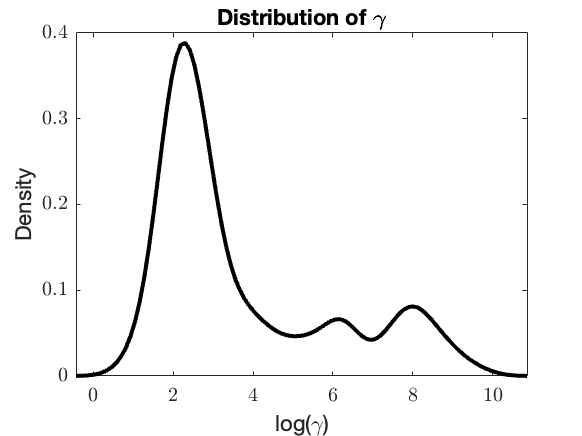


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\gamma)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_6.png','Resolution',300)



%Simplex
%Sigma
[f,xi] = ksdensity(log(gird(:,2)));
fprintf('\n SIMPLEX: median sigma = %.2f  ', median(gird(:,2)))


 SIMPLEX: median sigma = 0.30  

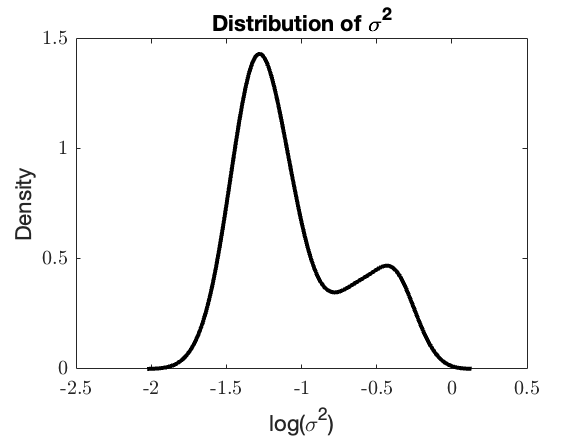



figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)

title('Distribution of \sigma^2');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\sigma^2)');
ylabel('Density');

f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_7.png','Resolution',300)



%Simplex
%Cost (error)
[f,xi] = ksdensity(log(gird(:,3)));
fprintf('\n SIMPLEX: median cost = %.2f  ', median(gird(:,3)))


 SIMPLEX: median cost = 0.01  

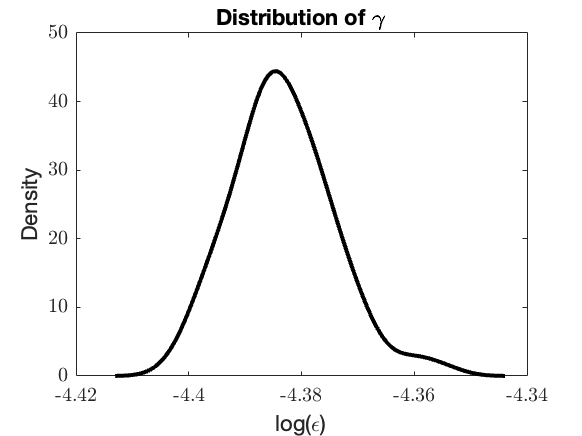


figure;
plot(xi,f,'Color', blackColor,'LineWidth',2)
title('Distribution of \gamma');
set(gca,'TickLabelInterpreter','latex');
xlabel('log(\epsilon)');
ylabel('Density');


f = gcf;
exportgraphics(f,'/Users/serg/github_projects/QASS_SVM/manuscript/figures2/fig2_221_8.png','Resolution',300)